# Single Objective Optimization Algorithms Notes

Udemy Algorithms Course

Dillon Allen

## Optimization Problems

### Particle Swarm Optimization (PSO)

#### $\vec{X_{i}^{d}}= \left[ x_i^{d}, y_i^d, z_i^d, \ldots \right]$, state vector

#### 
$$\vec{V_ i^{d+1}} = w \vec{V_i^d} + c_1 r_1 \left( \vec{P_i^d} - \vec{X_i^d} \right) + c_2 r_2 \left(\vec{G^d} - \vec{X_i^d}\right)$$


where $V_i^d$ is the current velocity, $P_i^d$ is the personal best solution, and $G^d$ is the global best solution. The first term is called the Inertial component, the second is the cognitive component, and the third is the social component. We need to tune the parameters.

 To find the next position, we calculate (dropping vectors).

#### 
$$X_i^{d+1} = X_i^d + V_i^{d+1}$$


###  Implementation

% define the details of the objective function
clc, clear;
nVar = 10;

ub = ones(1, nVar) .* 10;
lb = ones(1, nVar) .* -10;

fobj = @ObjectiveFunctionPSO;

% Define the PSO parameters
numP = 30;
maxIter = 500;
wMax = 0.9;
wMin = 0.2;
c1 = 2;
c2 = 2;

% The PSO Algorithm

% Initialize the particles

% create the struct
for k = 1 : numP
    Swarm.Particles(k).X = (ub - lb) .* rand(1, nVar) + lb;
    Swarm.Particles(k).V = zeros(1, nVar);
    Swarm.Particles(k).PBEST.X = zeros(1, nVar);
    Swarm.Particles(k).PBEST.O = inf;

    Swarm.GBEST.X = zeros(1, nVar);
    Swarm.GBEST.O = inf;
end

% Main Loop
for k = 1 : maxIter

    % Calculate the Objective Value
    for j = 1 : numP
        currentX = Swarm.Particles(j).X;
        Swarm.Particles(j).O = fobj(currentX);
        
        % Update PBEST
        if Swarm.Particles(j).O < Swarm.Particles(j).PBEST.O
            Swarm.Particles(j).PBEST.X = currentX;
            Swarm.Particles(j).PBEST.O = Swarm.Particles(j).O;
        end
        
        % Update GBEST
        if Swarm.Particles(j).O < Swarm.GBEST.O
            Swarm.GBEST.X = currentX; 
            Swarm.GBEST.O = Swarm.Particles(j).O;
        end
    end

    % Update the Position and Velocity Vectors
    w = wMax - k .* ((wMax - wMin)/maxIter);

    for i = 1 : numP
        inertialComp = w .* Swarm.Particles(i).V;
        cognitiveComp = c1.*rand(1, nVar).* ...
                        (Swarm.Particles(i).PBEST.X - Swarm.Particles(i).X);
        socialComp = c2.*rand(1,nVar).*(Swarm.GBEST.X - Swarm.Particles(i).X);
        Swarm.Particles(i).V = inertialComp + cognitiveComp + socialComp;

        Swarm.Particles(i).X = Swarm.Particles(i).X + Swarm.Particles(i).V;
    end

    outmsg = ['Iteration#', num2str(k), "GBEST.O", num2str(Swarm.GBEST.O)];
    disp(outmsg);

    cgCurve(k) = Swarm.GBEST.O;

end

    "Iteration#"    "1"    "GBEST.O"    "176.8313"

    "Iteration#"    "2"    "GBEST.O"    "114.8608"

    "Iteration#"    "3"    "GBEST.O"    "114.8608"

    "Iteration#"    "4"    "GBEST.O"    "113.603"

    "Iteration#"    "5"    "GBEST.O"    "113.603"

    "Iteration#"    "6"    "GBEST.O"    "113.603"

    "Iteration#"    "7"    "GBEST.O"    "113.603"

    "Iteration#"    "8"    "GBEST.O"    "113.603"

    "Iteration#"    "9"    "GBEST.O"    "113.603"

    "Iteration#"    "10"    "GBEST.O"    "113.603"

    "Iteration#"    "11"    "GBEST.O"    "112.7574"

    "Iteration#"    "12"    "GBEST.O"    "112.7574"

    "Iteration#"    "13"    "GBEST.O"    "112.7574"

    "Iteration#"    "14"    "GBEST.O"    "112.7574"

    "Iteration#"    "15"    "GBEST.O"    "112.7574"

    "Iteration#"    "16"    "GBEST.O"    "112.7574"

    "Iteration#"    "17"    "GBEST.O"    "112.7574"

    "Iteration#"    "18"    "GBEST.O"    "112.7574"

    "Iteration#"    "19"    "GBEST.O"    "112.7574"

    "Iter

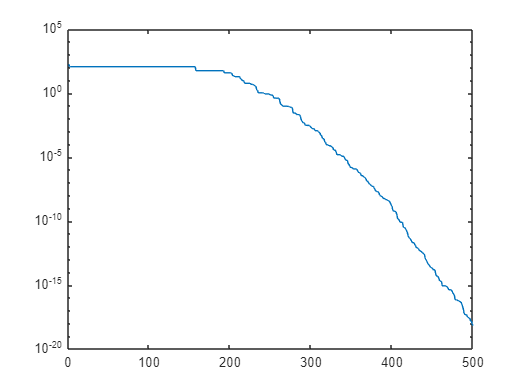

% Plot the convergence curve (semilogy to see more change approaching zero)
semilogy(cgCurve);

## PSO with Bounding Velocities and Bounding Positions

 We can bound the position and the velocities so the particles do not go out of frame very often.

This will improve performance and lower the objective result. 

% define the details of the objective function
clc, clear;
nVar = 10;

ub = ones(1, nVar) .* 10;
lb = ones(1, nVar) .* -10;

fobj = @ObjectiveFunctionPSO;

% Define the PSO parameters
numP = 30;
maxIter = 500;
wMax = 0.9;
wMin = 0.2;
c1 = 2;
c2 = 2;

% Rule of thumb for velocity bounds are 20%
vMax = (ub-lb)*.2;
vMin = -vMax;

% The PSO Algorithm

% Initialize the particles

% create the struct
for k = 1 : numP
    Swarm.Particles(k).X = (ub - lb) .* rand(1, nVar) + lb;
    Swarm.Particles(k).V = zeros(1, nVar);
    Swarm.Particles(k).PBEST.X = zeros(1, nVar);
    Swarm.Particles(k).PBEST.O = inf;

    Swarm.GBEST.X = zeros(1, nVar);
    Swarm.GBEST.O = inf;
end

% Main Loop
for k = 1 : maxIter

    % Calculate the Objective Value
    for j = 1 : numP
        currentX = Swarm.Particles(j).X;
        Swarm.Particles(j).O = fobj(currentX);
        
        % Update PBEST
        if Swarm.Particles(j).O < Swarm.Particles(j).PBEST.O
            Swarm.Particles(j).PBEST.X = currentX;
            Swarm.Particles(j).PBEST.O = Swarm.Particles(j).O;
        end
        
        % Update GBEST
        if Swarm.Particles(j).O < Swarm.GBEST.O
            Swarm.GBEST.X = currentX; 
            Swarm.GBEST.O = Swarm.Particles(j).O;
        end
    end

    % Update the Position and Velocity Vectors
    w = wMax - k .* ((wMax - wMin)/maxIter);

    for i = 1 : numP
        inertialComp = w .* Swarm.Particles(i).V;
        cognitiveComp = c1.*rand(1, nVar).* ...
                        (Swarm.Particles(i).PBEST.X - Swarm.Particles(i).X);
        socialComp = c2.*rand(1,nVar).*(Swarm.GBEST.X - Swarm.Particles(i).X);
        Swarm.Particles(i).V = inertialComp + cognitiveComp + socialComp;
        
        % Check velocities to make sure it isn't out of bounds
        index1 = find(Swarm.Particles(i).V > vMax);
        index2 = find(Swarm.Particles(i).V < vMin);

        Swarm.Particles(i).V(index1) = vMax(index1);
        Swarm.Particles(i).V(index2) = vMin(index2);

        Swarm.Particles(i).X = Swarm.Particles(i).X + Swarm.Particles(i).V;

        % Check position to make sure not out of bounds
        index1 = find(Swarm.Particles(i).X > ub);
        index2 = find(Swarm.Particles(i).X < lb);

        Swarm.Particles(i).X(index1) = ub(index1);
        Swarm.Particles(i).X(index2) = lb(index2);
    end

    outmsg = ['Iteration#', num2str(k), "GBEST.O", num2str(Swarm.GBEST.O)];
    disp(outmsg);

    cgCurve(k) = Swarm.GBEST.O;

end

    "Iteration#"    "1"    "GBEST.O"    "152.9713"

    "Iteration#"    "2"    "GBEST.O"    "60.5933"

    "Iteration#"    "3"    "GBEST.O"    "24.6358"

    "Iteration#"    "4"    "GBEST.O"    "24.6358"

    "Iteration#"    "5"    "GBEST.O"    "15.0446"

    "Iteration#"    "6"    "GBEST.O"    "7.7022"

    "Iteration#"    "7"    "GBEST.O"    "7.7022"

    "Iteration#"    "8"    "GBEST.O"    "7.7022"

    "Iteration#"    "9"    "GBEST.O"    "7.7022"

    "Iteration#"    "10"    "GBEST.O"    "7.7022"

    "Iteration#"    "11"    "GBEST.O"    "7.7022"

    "Iteration#"    "12"    "GBEST.O"    "7.7022"

    "Iteration#"    "13"    "GBEST.O"    "7.7022"

    "Iteration#"    "14"    "GBEST.O"    "7.7022"

    "Iteration#"    "15"    "GBEST.O"    "7.7022"

    "Iteration#"    "16"    "GBEST.O"    "7.7022"

    "Iteration#"    "17"    "GBEST.O"    "7.7022"

    "Iteration#"    "18"    "GBEST.O"    "6.4298"

    "Iteration#"    "19"    "GBEST.O"    "6.4298"

    "Iteration#"    "20"    "GBEST

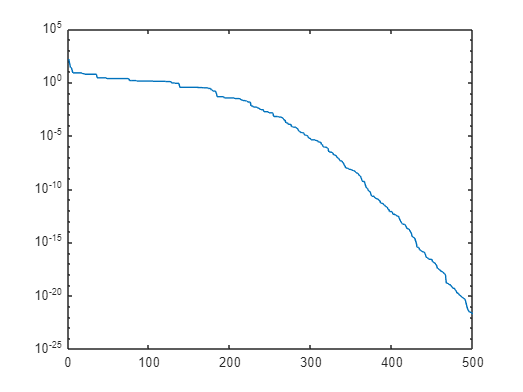

semilogy(cgCurve);

## Table Design PSO

Import PSO code from previous section and modify for Table Design

% define the details of the objective function
clc, clear;
nVar = 2;

ub = ones(1, nVar) .* 7;
lb = ones(1, nVar) .* 2;

fobj = @OurTableDesignProblem;

% Define the PSO parameters
numP = 2;
maxIter = 10;
wMax = 0.9;
wMin = 0.2;
c1 = 2;
c2 = 2;

% Rule of thumb for velocity bounds are 20%
vMax = (ub-lb).*0.2;
vMin = -vMax;

% The PSO Algorithm

% Initialize the particles

% create the struct
for k = 1 : numP
    Swarm.Particles(k).X = (ub - lb) .* rand(1, nVar) + lb;
    Swarm.Particles(k).V = zeros(1, nVar);
    Swarm.Particles(k).PBEST.X = zeros(1, nVar);
    Swarm.Particles(k).PBEST.O = inf;

    Swarm.GBEST.X = zeros(1, nVar);
    Swarm.GBEST.O = inf;
end

% Main Loop
for k = 1 : maxIter

    % Calculate the Objective Value
    for j = 1 : numP
        currentX = Swarm.Particles(j).X;
        Swarm.Particles(j).O = fobj(currentX);
        
        % Update PBEST
        if Swarm.Particles(j).O < Swarm.Particles(j).PBEST.O
            Swarm.Particles(j).PBEST.X = currentX;
            Swarm.Particles(j).PBEST.O = Swarm.Particles(j).O;
        end
        
        % Update GBEST
        if Swarm.Particles(j).O < Swarm.GBEST.O
            Swarm.GBEST.X = currentX; 
            Swarm.GBEST.O = Swarm.Particles(j).O;
        end
    end

    % Update the Position and Velocity Vectors
    w = wMax - k .* ((wMax - wMin)/maxIter);

    for i = 1 : numP
        inertialComp = w .* Swarm.Particles(i).V;
        cognitiveComp = c1.*rand(1, nVar).* ...
                        (Swarm.Particles(i).PBEST.X - Swarm.Particles(i).X);
        socialComp = c2.*rand(1,nVar).*(Swarm.GBEST.X - Swarm.Particles(i).X);
        Swarm.Particles(i).V = inertialComp + cognitiveComp + socialComp;
        
        % Check velocities to make sure it isn't out of bounds
        index1 = find(Swarm.Particles(i).V > vMax);
        index2 = find(Swarm.Particles(i).V < vMin);

        Swarm.Particles(i).V(index1) = vMax(index1);
        Swarm.Particles(i).V(index2) = vMin(index2);

        Swarm.Particles(i).X = Swarm.Particles(i).X + Swarm.Particles(i).V;

        % Check position to make sure not out of bounds
        index1 = find(Swarm.Particles(i).X > ub);
        index2 = find(Swarm.Particles(i).X < lb);

        Swarm.Particles(i).X(index1) = ub(index1);
        Swarm.Particles(i).X(index2) = lb(index2);
    end

    outmsg = ['Iteration#', num2str(k), "GBEST.O", num2str(Swarm.GBEST.O)];
    disp(outmsg);

    cgCurve(k) = Swarm.GBEST.O;

end

    "Iteration#"    "1"    "GBEST.O"    "7.9111"

    "Iteration#"    "2"    "GBEST.O"    "7.9111"

    "Iteration#"    "3"    "GBEST.O"    "7.9111"

    "Iteration#"    "4"    "GBEST.O"    "6.9224"

    "Iteration#"    "5"    "GBEST.O"    "6.2264"

    "Iteration#"    "6"    "GBEST.O"    "5.8879"

    "Iteration#"    "7"    "GBEST.O"    "5.5117"

    "Iteration#"    "8"    "GBEST.O"    "5.3574"

    "Iteration#"    "9"    "GBEST.O"    "5.1743"

    "Iteration#"    "10"    "GBEST.O"    "5.0308"



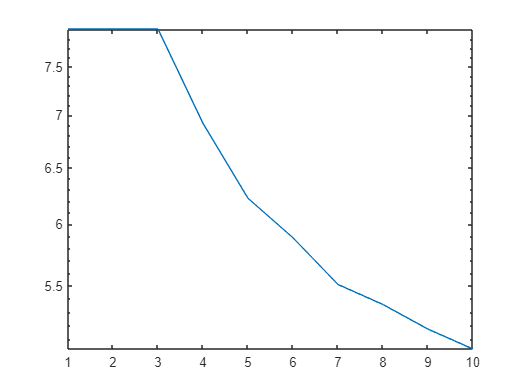


semilogy(cgCurve);

## Constrained Optimization

Penalty Methods (adding 200 with constraint is violated)

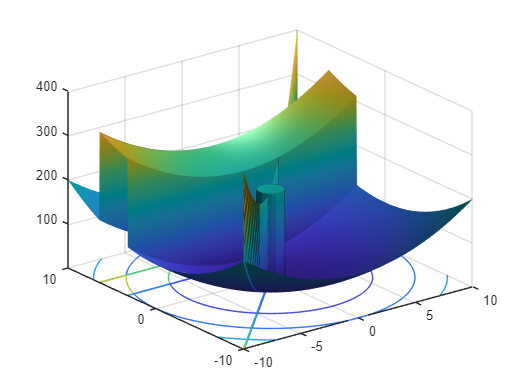

% visualize the landscape

fobj = @ObjectiveFunctionConst;

x = -10 : 0.05 : 10;
y = x;

[x_new, y_new] = meshgrid(x,y);

for i = 1 : size(x_new,1)
    for j = 1: size(x_new,2)
        currentX = [x_new(i,j), y_new(i,j)];
        o(i,j) = fobj(currentX);
    end
end

surfc(x_new, y_new, o)
shading interp
camlight

Now conduct the PSO with this constrained function

% define the details of the objective function
clc, clear;
nVar = 2;

ub = ones(1, nVar) .* 10;
lb = ones(1, nVar) .* -10;

fobj = @ObjectiveFunctionConst;

% Define the PSO parameters
numP = 30;
maxIter = 500;
wMax = 0.9;
wMin = 0.2;
c1 = 2;
c2 = 2;

% Rule of thumb for velocity bounds are 20%
vMax = (ub-lb)*.2;
vMin = -vMax;

% The PSO Algorithm

% Initialize the particles

% create the struct
for k = 1 : numP
    Swarm.Particles(k).X = (ub - lb) .* rand(1, nVar) + lb;
    Swarm.Particles(k).V = zeros(1, nVar);
    Swarm.Particles(k).PBEST.X = zeros(1, nVar);
    Swarm.Particles(k).PBEST.O = inf;

    Swarm.GBEST.X = zeros(1, nVar);
    Swarm.GBEST.O = inf;
end

% Main Loop
for k = 1 : maxIter

    % Calculate the Objective Value
    for j = 1 : numP
        currentX = Swarm.Particles(j).X;
        Swarm.Particles(j).O = fobj(currentX);
        
        % Update PBEST
        if Swarm.Particles(j).O < Swarm.Particles(j).PBEST.O
            Swarm.Particles(j).PBEST.X = currentX;
            Swarm.Particles(j).PBEST.O = Swarm.Particles(j).O;
        end
        
        % Update GBEST
        if Swarm.Particles(j).O < Swarm.GBEST.O
            Swarm.GBEST.X = currentX; 
            Swarm.GBEST.O = Swarm.Particles(j).O;
        end
    end

    % Update the Position and Velocity Vectors
    w = wMax - k .* ((wMax - wMin)/maxIter);

    for i = 1 : numP
        inertialComp = w .* Swarm.Particles(i).V;
        cognitiveComp = c1.*rand(1, nVar).* ...
                        (Swarm.Particles(i).PBEST.X - Swarm.Particles(i).X);
        socialComp = c2.*rand(1,nVar).*(Swarm.GBEST.X - Swarm.Particles(i).X);
        Swarm.Particles(i).V = inertialComp + cognitiveComp + socialComp;
        
        % Check velocities to make sure it isn't out of bounds
        index1 = find(Swarm.Particles(i).V > vMax);
        index2 = find(Swarm.Particles(i).V < vMin);

        Swarm.Particles(i).V(index1) = vMax(index1);
        Swarm.Particles(i).V(index2) = vMin(index2);

        Swarm.Particles(i).X = Swarm.Particles(i).X + Swarm.Particles(i).V;

        % Check position to make sure not out of bounds
        index1 = find(Swarm.Particles(i).X > ub);
        index2 = find(Swarm.Particles(i).X < lb);

        Swarm.Particles(i).X(index1) = ub(index1);
        Swarm.Particles(i).X(index2) = lb(index2);
    end

    outmsg = ['Iteration#', num2str(k), "GBEST.O", num2str(Swarm.GBEST.O)];
    disp(outmsg);

    cgCurve(k) = Swarm.GBEST.O;

end

    "Iteration#"    "1"    "GBEST.O"    "3.5618"

    "Iteration#"    "2"    "GBEST.O"    "3.5618"

    "Iteration#"    "3"    "GBEST.O"    "1.9416"

    "Iteration#"    "4"    "GBEST.O"    "1.2704"

    "Iteration#"    "5"    "GBEST.O"    "1.2704"

    "Iteration#"    "6"    "GBEST.O"    "1.1138"

    "Iteration#"    "7"    "GBEST.O"    "1.1138"

    "Iteration#"    "8"    "GBEST.O"    "1.1138"

    "Iteration#"    "9"    "GBEST.O"    "1.1138"

    "Iteration#"    "10"    "GBEST.O"    "1.0111"

    "Iteration#"    "11"    "GBEST.O"    "1.0002"

    "Iteration#"    "12"    "GBEST.O"    "1.0002"

    "Iteration#"    "13"    "GBEST.O"    "1.0002"

    "Iteration#"    "14"    "GBEST.O"    "1.0002"

    "Iteration#"    "15"    "GBEST.O"    "1.0002"

    "Iteration#"    "16"    "GBEST.O"    "1.0002"

    "Iteration#"    "17"    "GBEST.O"    "1.0002"

    "Iteration#"    "18"    "GBEST.O"    "1.0002"

    "Iteration#"    "19"    "GBEST.O"    "1.0002"

    "Iteration#"    "20"    "GBEST.O"   

fprintf("Location of GBEST: (%f, %f)", Swarm.GBEST.X)

Location of GBEST: (-0.994891, 0.100954)

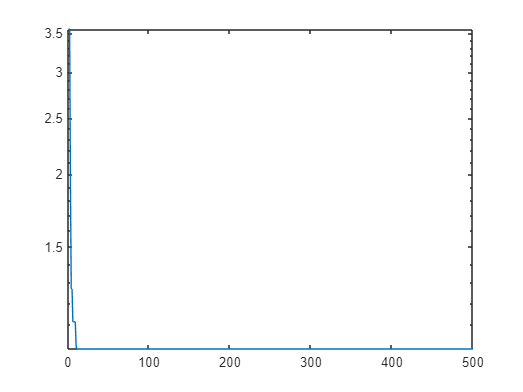

semilogy(cgCurve)

## Functions

function [o] = ObjectiveFunctionPSO (x)
    o = sum(x.^2);
end

function [o] = ObjectiveFunctionConst(x)
   const1 = x(2) <= 3.2 || x(2) > 6.4;
   const2 = (x(1)^2 + x(2)^2) >= 1;
   const3 = x(1) ~= x(2);
   
   if const1 == 1 && const2 == 1 && const3 == 1
       o = sum (x.^2); % spherical test function
   else
       % the solution is not feasible
       o = sum(x.^2) + 200;
   end

end

function [weight] = OurTableDesignProblem(x)
    length = x(1);
    width = x(2);

    weight = 1.*(length + width);
end